# Post Process Radar Data

Script Summary

- Read key information on the MMWave Device

- Generate an ADC Data Cube sorted by (frame,chirp, rx channel, sample

- Compute Range Doppler Plot

Assumptions:

- Using IWR1443 Radar

## Read mmWave Device Information

Start by declaring the location of the adc_data.bin, mmwave.json, and setup.json files are located. If the location is known, put them into the script, otherwise, there are helper functions to get the files as needed

clear;
%if the file locations are known, list them here

%for mac
% data_path = '/Users/David/OneDrive - Duke University/Radar Security Project/Matlab Processing/Data Sets/hand_gesture_samples/9_gesture_recordings_revC';
% adc_data_file_name = strcat(data_path,'/swipe_left_to_right/adc_data_20.bin');
% mmwave_setup_json_file_name = strcat(data_path,'/mmWaveDevice_info/JSON/mmwave_configuration.mmwave.json');

%for windows - gesture recognition
% data_path = 'C:\Users\Operator\OneDrive - Duke University\Radar Security Project\Matlab Processing\Data Sets\hand_gesture_samples\9_gesture_recordings_revC';
% adc_data_file_name = strcat(data_path,['\twist_fingers_counterclockwise\adc_data_1.bin']);
% mmwave_setup_json_file_name = strcat(data_path,'\mmWaveDevice_info\JSON\mmwave_configuration.mmwave.json');

%for windows - attacker_defender_configurations
% data_path = 'C:\Users\Operator\OneDrive - Duke University\Radar Security Project\Matlab Processing\Data Sets\attacker_defender_experiments_mar_4_2022\attack_7_2 attack chirp per defense chirp same slope_closer frames';
% adc_data_file_name = strcat(data_path,'\PostProc\adc_data.bin');
% mmwave_setup_json_file_name = strcat(data_path,'\JSON\mmwave_configuration.mmwave.json');

%for ubuntu
% data_path = "/home/david/Documents/mmWave_data/AoA testing_mar_1_2023";
% adc_data_file_name = strcat(data_path,"/adc_data.bin");
% mmwave_setup_json_file_name = strcat(data_path,"/config/mmWave_config.mmwave.json");


% mmwave_json_file_name = GET_MMWAVE_SETUP_JSON_FILE(mmwave_setup_json_file_name);
% adc_bin_file_name = GET_ADC_DATA_BIN_FILE(adc_data_file_name);

%otherwise use these helper functions
mmwave_json_file_name = GET_MMWAVE_SETUP_JSON_FILE();

User selected C:\Users\david\Documents\TI_Radar_Demo_Visualizer\Python Modules\DCA_1000\MATLAB Code\Sample_Data\mmwave.mmwave.json 


adc_bin_file_name = GET_ADC_DATA_BIN_FILE()

User selected C:\Users\david\Documents\TI_Radar_Demo_Visualizer\Python Modules\DCA_1000\MATLAB Code\Sample_Data\adc_data.bin 


adc_bin_file_name = 'C:\Users\david\Documents\TI_Radar_Demo_Visualizer\Python Modules\DCA_1000\MATLAB Code\Sample_Data\adc_data.bin'

Next, instantiate a MMWaveDeviceClass which reads the mmwave.setup file to obtain all necessary information from the mmWave Device

mmWave_device = MMWaveDevice(adc_bin_file_name,mmwave_json_file_name);
mmWave_device.printDeviceConfiguration();

# of sample/chirp: 256
# of chirp/frame: 128
# of sample/frame: 131072
Size of one frame: 524288 Bytes
# of frames in the raw ADC data file: 8

Rx channels enabled: [1,1,1,1]
#of Rx channels: 4

Radar bandwidth: 0.77 (GHz)

ADC sampling rate: 10.00 (MSa/s)
ADC bits: 16 bit
dBFS scaling factor: -129.48 (dB)

Chirp duration: 160.00 (usec)
Chirp slope: 29.98 (MHz/usec)
Chirp bandwidth: 767.54 (MHz)
Chirp "valid" duration: 25.60 (usec)

Frame length: 20.48 (msec)
Frame periodicity: 40.00 (msec)
Frame duty-cycle: 0.51 

Range limit: 49.9954 (m)
Range resolution: 0.1953 (m)
Velocity limit: 6.0835 (m/s)
Velocity resolution: 0.0951 (m/s)

IQ swap?: 0
Interleaved data?: 0
...System configuration imported!



## Generate ADC Data Cube

First, use the helper function to read the adc_data.bin file and sort the data into a continuous stream of samples for each LVDS lane (each Rx Channel)

raw_adc_data = READ_ADC_DATA_BIN_FILE(adc_bin_file_name,mmWave_device);

Next we generate the adc_data_cube which will be indexed as follows:

- adc_data_cube[rx channel, sample, chirp, frame]

num_frames = mmWave_device.num_frame;
chirps_per_frame = mmWave_device.num_chirp_per_frame;
rx_channels = mmWave_device.num_rx_chnl;
samples_per_chirp = mmWave_device.num_sample_per_chirp;


%generate an adc_data_cube
adc_data_cube = reshape(raw_adc_data,rx_channels,samples_per_chirp,chirps_per_frame,num_frames);

%print data from 1st chirp of 1st frame
adc_data_cube(:,:,1,1);
%print shape of the adc_data_cube
size(adc_data_cube)

ans =      4   256   128     8


### Plot a desired Frame and Chirp

Code to setup the plot

sampling_period = 1/mmWave_device.adc_samp_rate;
t = 0:sampling_period:sampling_period*samples_per_chirp - sampling_period;

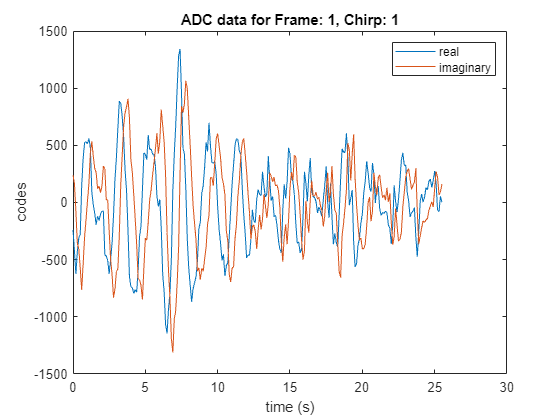

clf;
%Desired Frame
desired_frame = 1;
%Desired Chirp
desired_chirp = 1;
%Desired Rx Channel - Hardcoded to channel 1 for now
rx_channel = 1;
data = adc_data_cube(rx_channel,:,desired_chirp,desired_frame);
real_data = real(data);
imaginary_data = imag(data);
plot(t,real_data,t,imaginary_data)
xlabel('time (s)');
ylabel('codes');
title_str = sprintf('ADC data for Frame: %d, Chirp: %d',desired_frame, desired_chirp);
title(title_str);
legend('real','imaginary');

## Range FFT

### Calculate and plot range FFT for a single chirp

ranges = (0:mmWave_device.num_sample_per_chirp - 1) * mmWave_device.range_res;

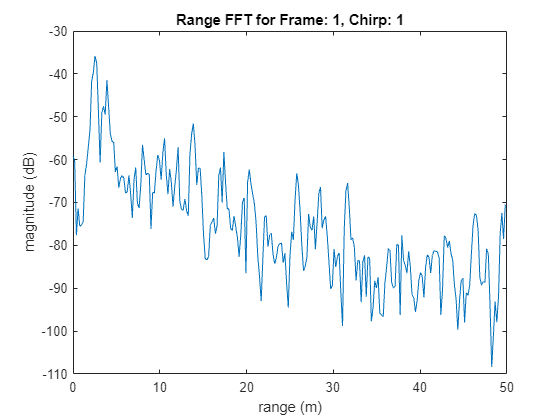

clf;
%Desired Frame
desired_frame = 1;
%Desired Chirp
desired_chirp = 1;
%Desired Rx Channel - Hardcoded to channel 1 for now
rx_channel = 1;

fft_ = 20 * log10(abs(fft( ...
    mmWave_device.win_hann.' .* ...
    adc_data_cube(rx_channel,:,desired_chirp,desired_frame)))); 
plot(ranges,abs(fft_) + mmWave_device.dbfs_coeff); %apply the dbfs coeff when performing the offset
xlabel('range (m)')
ylabel('magnitude (dB)')
title_str = sprintf('Range FFT for Frame: %d, Chirp: %d',desired_frame, desired_chirp);
title(title_str);

### Plot Range FFT next to ADC Plot for a desired Chirp and Frame

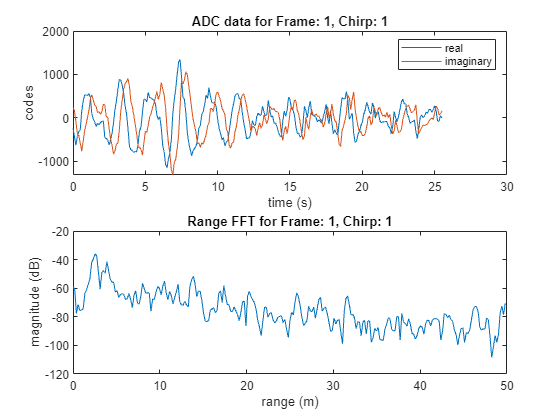

clf;
%Desired Frame
desired_frame = 1;
%Desired Chirp
desired_chirp = 1;
%Desired Rx Channel - Hardcoded to channel 1 for now
rx_channel = 1;



%adc data calculation
data = adc_data_cube(rx_channel,:,desired_chirp,desired_frame);
real_data = real(data);
imaginary_data = imag(data);
subplot(2,1,1)
plot(t,real_data,t,imaginary_data)
xlabel('time (s)');
ylabel('codes');
title_str = sprintf('ADC data for Frame: %d, Chirp: %d',desired_frame, desired_chirp);
title(title_str);
legend('real','imaginary');

%fft calculation
fft_ = 20 * log10(abs(fft( ...
    mmWave_device.win_hann.' .* ...
    adc_data_cube(rx_channel,:,desired_chirp,desired_frame)))); subplot(2,1,2);
plot(ranges,abs(fft_) + mmWave_device.dbfs_coeff); %apply the dbfs coeff when performing the offset
xlabel('range (m)')
ylabel('magnitude (dB)')
title_str = sprintf('Range FFT for Frame: %d, Chirp: %d',desired_frame, desired_chirp);
title(title_str);

## Generate Range-Azimuth plot using fft

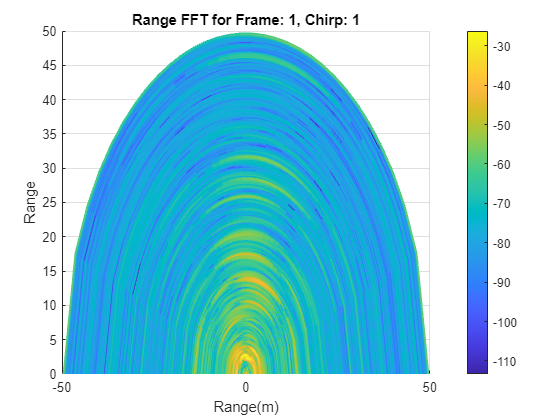

%obtain the data for all 4 channels at a specific chirp and frame index
clf;
desired_frame = 8;
desired_chirp = 1;

%determine the angular coordinates and the associated AoA
num_angle_bins = 32;
angles = (-1 * pi:2 * pi/(num_angle_bins - 1):pi) * -1;
AoA_coordinates_rad = asin(angles/pi);

%define the amount of zero padding to add
range_angle_cube = zeros(mmWave_device.num_sample_per_chirp,num_angle_bins);

%obtain the frame data
frame_data = adc_data_cube(:,:,desired_chirp,desired_frame).';
range_angle_cube(:,1:mmWave_device.num_rx_chnl) = fft(mmWave_device.win_hann .* frame_data);
range_angle_cube = fftshift(fft(range_angle_cube,num_angle_bins,2),2);
% 
% frame_data = 20*log10(abs(fft_2d_range_cube(:,:,desired_frame)));
x_vals = AoA_coordinates_rad;
% imagesc(x_vals,ranges, 20 * log10(abs(range_angle_cube)));
[thetas,rhos] = meshgrid(AoA_coordinates_rad,ranges);
[X,Y] = pol2cart(thetas,rhos);
surf(X,Y, 20 * log10(abs(range_angle_cube)) + mmWave_device.dbfs_coeff,'EdgeColor','none');
view(90,270)
%title_str = sprintf('2D Range FFT for frame: %d',desired_frame);
title(title_str);
xlabel('Range')
ylabel('Range(m)')
zlabel('Magnitude (dB)')
colorbar;